# Genetic Algorithm with Matlab Toolbox Examples

#### Prepared by: Yuanfei Wang

#### Date: 05 July 2022

clc
clear
close all

### Model Setup and Initialisation

Initialisation of EPANET Matlab toolkit and loading of .net file.

epanet_path = 'E:\Program Files\MATLAB\R2021b\toolbox\epanet\EPANET-Matlab-Toolkit-master';
net_id = 'example1';
run( [epanet_path,'\start_toolkit'])

EPANET-MATLAB Toolkit Paths Loaded.


net = epanet([net_id,'.inp']);

EPANET version {20200} loaded (EMT version {v2.2.0}).
Loading File "example1.inp"...
Input File "example1.inp" loaded sucessfuly.


### Graph Creation

Use graph theory to plot network connectivity and spatial coordinates.

% Save element count variables
nt = 24; % number of time steps in hours
nn = net.NodeJunctionCount;
n0 = net.NodeReservoirCount;
np = net.LinkCount; % count of pipes and valves
D = net.getLinkDiameter';

% Save node index vectors
Reservoir_Idx = net.getNodeReservoirIndex;
Junction_Idx = net.getNodeJunctionIndex;

% Specify hydraulic and quality time steps (in seconds)
net.setTimeQualityStep(15*60); % 15 minute quality time steps
net.setTimeHydraulicStep(15*60); % 15 minute hydraulic time steps
days = 3; % simulation duration in days; change this variable to change overall simualtion time
net.setTimeSimulationDuration(days*(nt*3600)); % load modified simulation duration from initial .inp file

% Initialise EPANET simulation type
net.setQualityType('Chemical','mg/L');
net.setNodeSourceQuality(1:nn+n0,zeros(nn+n0,1)); % set all node source quality to zero

% Link bulk reaction coefficients
lambda = 0.5*ones(np,1); % units of days^-1
net.setLinkBulkReactionCoeff(1:np, -lambda);
net.setOptionsPipeBulkReactionOrder(1);

c0 = zeros(nn+n0,nt);
net.setNodeInitialQuality(net.NodeIndex,c0);

% Assign source chlorine with time varying pattern
cext = ones(n0,4*days*nt);

% Varying source concentration by source element
source_c = [1.00, 0.85];

for j = 1:n0
    cext(j,:) = source_c(j)*cext(j,:);
end
base_cext = ones(n0,1); 
pattern_cext = cext./(base_cext*ones(1,size(cext,2))); % extend vector over nt columns 

for i=1:n0
    patternId = sprintf('Res_C_%d',i);
    net.addPattern(patternId,pattern_cext(i,:));
    net.setNodeSourcePatternIndex(net.NodeReservoirIndex(i),net.getPatternIndex(patternId));
    net.setNodeSourceQuality(net.NodeReservoirIndex(i),base_cext(i));
    net.setNodeSourceType(net.NodeReservoirIndex(i),'CONCEN');  
end


% Create A12 and A10 incidence matrices
LinkNodesList = net.getLinkNodesIndex;

A = zeros(np,nn+n0);
for k=1:np
    i = LinkNodesList(k,1);
    j = LinkNodesList(k,2);
    A(k,i) = -1;
    A(k,j) = 1;
end

A12 = A(:,Junction_Idx);
A10 = A(:,Reservoir_Idx);
A12 = sparse(A12);
A10 = sparse(A10);

% Obstain node XY and elevation information
XY = zeros(nn+n0,2);
XY(:,1) = net.getNodeCoordinates{1};
XY(:,2) = net.getNodeCoordinates{2};
elev = double(net.getNodeElevations(Junction_Idx))';

% Create adjacency matrix
A = [A12,A10];
AdjA = sparse(size(A,2),size(A,2));

for k = 1:size(A,1)
    node_in = find(A(k,:) == -1);
    node_out = find(A(k,:) == 1);
    AdjA(node_in,node_out) = 1;
    AdjA(node_out,node_in) = 1;
end
gr = graph(AdjA);


% Calculate the result
hyd_res = net.getComputedHydraulicTimeSeries;
pressure = net.getNodePressure;
demand = net.getNodeActualDemand;
flow = net.getLinkFlows;
roughness = net.getLinkRoughnessCoeff;
% net.setQualityType('Age');
% net.setNodeSourceQuality(1:nn+n0,zeros(nn+n0,1)); % set all node source quality to zero
qua_res = net.getComputedQualityTimeSeries;
LinkIdx = net.getLinkIndex;
c_nodes = qua_res.NodeQuality';
c_pipes = qua_res.LinkQuality';
qual_sim = c_nodes;


%  r = a + (b-a).*rand(N,1) produce random numbers range from [a,b] 
mse_fun = @(sim, obs) (1/size(obs,1)/size(obs,2))*sum(sum((sim - obs).^2));
rand_qual = 0.99 + (1-0.99).*rand(nn+n0,1+nt*4*days); 
qual_obs = qual_sim.*rand_qual-0.05;
mse_before = mse_fun(qual_sim, qual_obs);

% Plot of network
figure
i = 227

i = 227

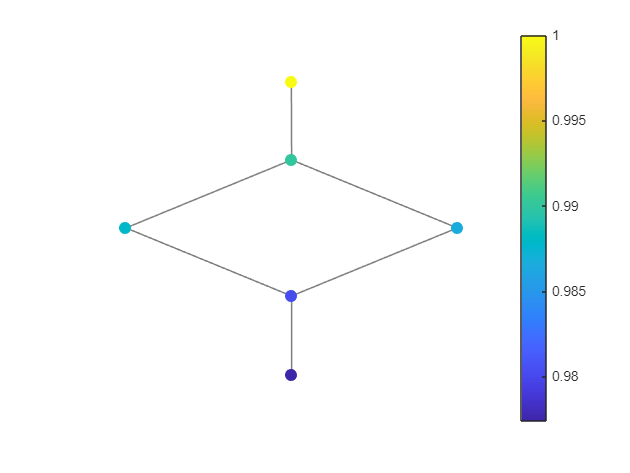

p1 = plot(gr);
p1.XData = XY(:,1);
p1.YData = XY(:,2);
p1.LineWidth = 1;
p1.EdgeColor = 'k';
p1.MarkerSize = 7;
p1.NodeColor = 'b';
p1.NodeLabel = '';
p1.NodeFontSize = 11;
p1.NodeLabelColor = [0.6350 0.0780 0.1840];
p1.NodeFontWeight = 'bold';

p1.NodeCData = c_nodes(:,i);
colorbar
axis('off')

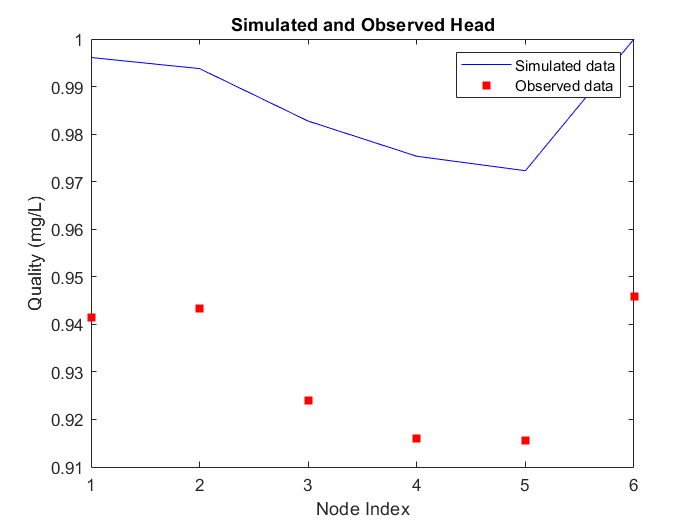

% Plot the calibrated quality-time figure at sensor1
figure,
plot(1:6,qual_sim(:,289),'-b')
hold on
scatter(1:6,qual_obs(:,289),'red','filled','square')
legend({'Simulated data','Observed data'})
xlabel('Node Index')
ylabel('Quality (mg/L)')
xticks(1:1:6);
title('Simulated and Observed Head')

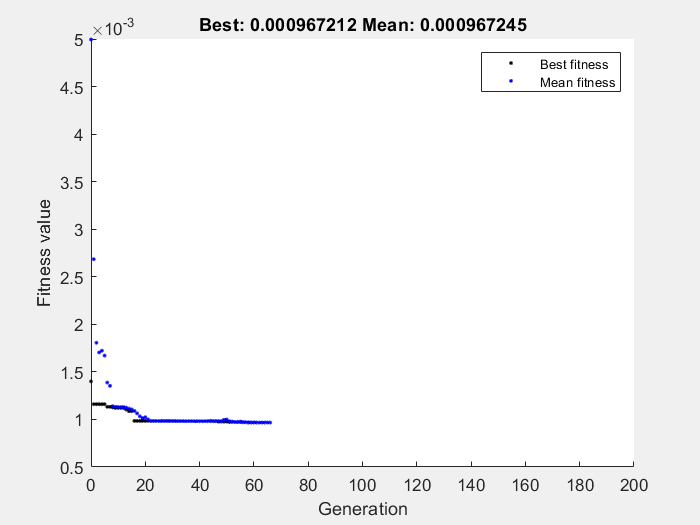


% % Optimize
% options = optimoptions('ga','PopulationType','DoubleVector','PopulationSize',6,'InitialPopulation', ...
%     [50,60,70,80,90,100],'Generations',50,"ConstraintTolerance",1e-3,"PlotFcn","gaplotbestf");

rng default
options = optimoptions('ga','Display','none','PopulationType','DoubleVector','PopulationSize',6,'InitialPopulation', ...
    [50,60,70,80,90,100],'Generations',200,"ConstraintTolerance",1e-8,"PlotFcn","gaplotbestf");
lb = [-10,-10,-10,-10,-10,-10];
ub = [0,0,0,0,0,0];

% rng default
% options = optimoptions('ga','Display','none','PopulationType','DoubleVector','PopulationSize',1,'InitialPopulation', ...
%     100,'Generations',200,"ConstraintTolerance",1e-8,"PlotFcn","gaplotbestf");
% lb = -10;
% ub = 0;

Mse_function = @(x) Mse(x,qual_obs);

% [x, fval] = ga(Mse_function,6,[],[],[],[],[],[],[],options);
[x, fval] = ga(Mse_function,6,[],[],[],[],lb,ub,[],options);

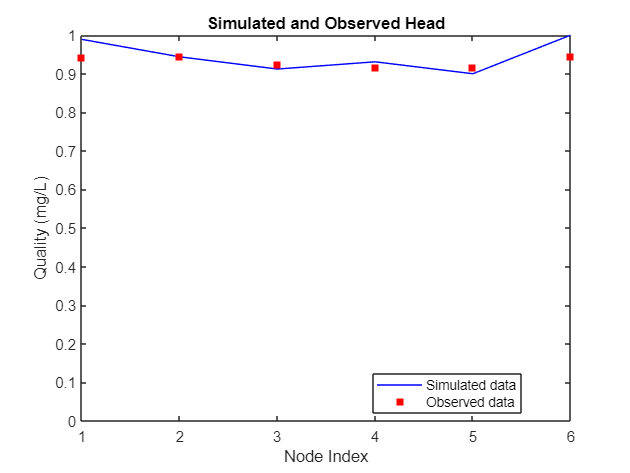

% Plot the calibrated quality-time figure at sensor1
% epanet_path = 'E:\Program Files\MATLAB\R2021b\toolbox\epanet\EPANET-Matlab-Toolkit-master';
% net_id = 'example1';
% run( [epanet_path,'\start_toolkit'])
% net = epanet([net_id,'.inp']);
for i = 1:6
    net.setLinkBulkReactionCoeff(LinkIdx(i),x(i));
end

net.getLinkBulkReactionCoeff;
net.getComputedQualityTimeSeries;
qual_ga = net.getNodeActualQuality';
mse_after = mse_fun(qual_ga, qual_obs);


figure,
plot(1:6,qual_ga,'-b')
hold on
scatter(1:6,qual_obs(:,end),'red','filled','square')
legend({'Simulated data','Observed data'},'Location','best')
xlabel('Node Index')
ylabel('Quality (mg/L)')
ylim([0,1])
title('Simulated and Observed Head')

% Result
fprintf('The mse before ga is %.4f, and the mse after ga is %.8f', mse_before, fval);

The mse before ga is 0.0030, and the mse after ga is 0.00096721